# 公司流量数据分析实验

clear;
datapath = 'data3.xlsx'; % 公司流量数值化后的数据

## 读入数据

data = xlsread(datapath);
num = data(:,1);
date = data(:,2);
flow = data(:,3);
attack = data(:,4);
intercept = data(:,5);
visit = data(:,6);
disp('数据读取完成！');

数据读取完成！


## 缺失值检测

nanvalue = find(isnan(data));
if isempty(nanvalue) %  没有缺失值
    disp('没有缺失值！');
else
    rows_ = size(nanvalue,1);
    disp(['缺失值个数为：' num2str(rows_) ',缺失率为：' num2str(rows_/rows)]);
end

没有缺失值！


disp('数据缺失值检测完成！');

数据缺失值检测完成！


## 异常值检测

箱形图上下界

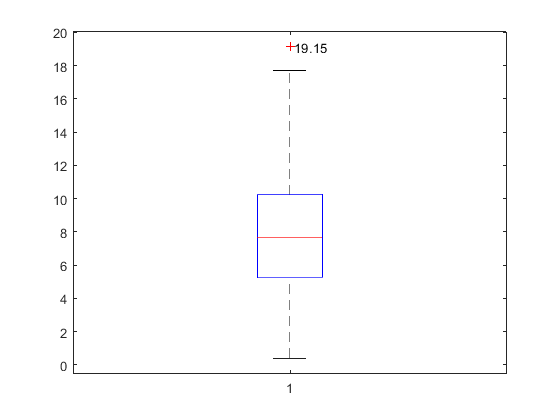

q_= prctile(flow,[25,75]);
p25=q_(1,1);
p75=q_(1,2);
upper = p75+ 1.5*(p75-p25);
lower = p25-1.5*(p75-p25);
upper_indexes = flow(flow>upper);
lower_indexes = flow(flow<lower);
indexes =[upper_indexes;lower_indexes];
indexes = sort(indexes);
% 箱形图
figure
hold on;
boxplot(flow,'whisker',1.5,'outliersize',6);
rows = size(indexes,1);
flag =0;
for i =1:rows
  if flag ==0
    text(1+0.01,indexes(i,1),num2str(indexes(i,1)));
    flag=1;
  else
      text(1-0.017*length(num2str(indexes(i,1))),indexes(i,1),num2str(indexes(i,1)));
    flag=0;
  end
end
hold off;

disp('数据异常值检测完成！');

数据异常值检测完成！


## 多元非线性曲线拟合

% 建立回归模型
mymodel = inline('beta0(1)*attack.^3 + beta0(2)*intercept.^2 + beta0(3)*log2(visit)','beta0','x');

% 回归
beta0=[1,1,1];%系数初始值
x = [attack,intercept,visit]; %自变量
y = flow;% 因变量
[b,r] = nlinfit(x,y,mymodel,beta0); %回归得到系数beta

错误使用 nlinfit (line 207)
Error evaluating inline model function.